# The free surface model by Elperin and Vikhansky, 1998

# 
$$h(x) = \frac{\frac{7}{8} \left(\frac{\Omega}{2}\right)^{\frac{6}{5}} \ \left[1.26 - (1 - x^2)^\frac{6}{5}\right] - \sin(\mu) \left(\frac{\Omega}{2}\right)^\frac{2}{5} \ \left[1.46 - (1 - x^2)^\frac{2}{5}\right]}{\cos(\mu) + \sin(\mu)}$$


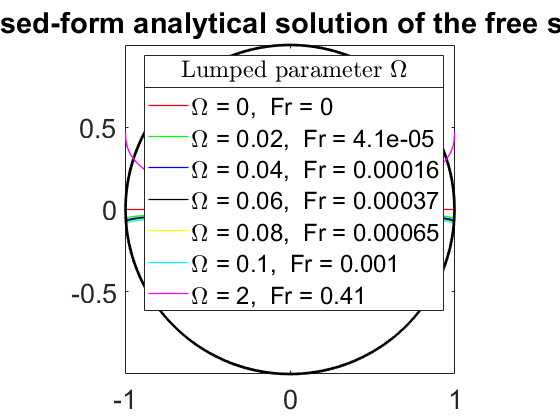

close all
for i = 1:7
col = 'rgbkycm';
ep = 0.1;
R = 1;
g = 9.81;
Nc = 42.3/sqrt(2*R);
om = [0,0.02,0.04,0.06,0.08,0.1,2];
omega = double(om(i));
Fr = double(omega^2*R/g);
R = 1;
g = 9.81;
%OMega = sqrt(ep^-3*(omega^2*R/g));
OMega = om(i);
muu = 0.35;
x = linspace(-R,R,1000);
h = ((7/8)*(OMega*0.5)^(6/5) *(1.26 - (1-x.^2).^(2/5)) - sin(muu)*(OMega*0.5)^(2/5)*(1.46 - (1 - x.^2).^(2/5)))/(sin(muu) + cos(muu));
dom = linspace(-R,R,1000);
upp = sqrt(R^2 - x.^2);
low = -sqrt(R^2 - x.^2);
plot(x,upp,'color','k','LineWidth',2,'HandleVisibility','off')
hold on 
plot(x,low,'color','k','LineWidth',2,'HandleVisibility','off')
axis equal; axis tight
hold on 
plot(x,h,col(i),'LineWidth',1,"DisplayName",['\Omega = ',num2str(OMega,2),',  Fr = ',num2str(Fr,2)],'HandleVisibility','on')
end
leg = legend('show');
set(gca,'FontSize',20)
title(leg,'Lumped parameter $\Omega$','Interpreter',"latex")
title('A closed-form analytical solution of the free surface')